EE3510 HW5 105060012張育菘

CP 8.1 

Consider the closed-loop transfer function $T\left(s\right)=\frac{25}{s^2 +s+25}$

Develop an m-file to, obtain the Bode plot and verify that the resonant frequency is 5 rad/s and that the peak magnitude Mpw is 14 dB.

close all; clear;
fprintf("CP8.1 \n");

CP8.1 



num = [25]; den = [1 1 25];
sys = tf(num, den);
w = logspace(0,1,500);

[mag, phase] = bode(sys, w);
[mp, wr_index] = max(mag);
mp_log = 20*log10(mp); wr = w(wr_index);

fprintf("Mpw = %f dB, wr = %f rad/s", mp_log, wr);

Mpw = 14.021586 dB, wr = 4.958962 rad/s

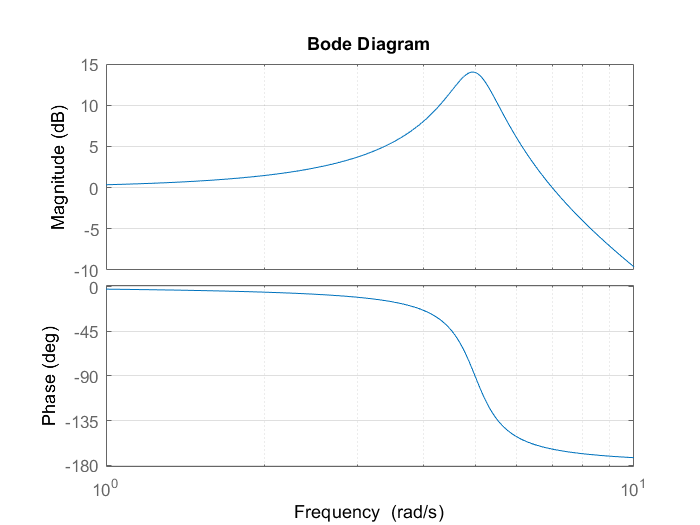

figure; bode(sys, w); grid on;

CP 8.4

A unity negative feedback system has the loop transfer function $G_c \left(s\right)G\left(s\right)=\frac{54}{s\left(s+6\right)}$.

Determine the closed-loop system bandwidth. Using the bode function obtain the Bode plot and label the plot with the bandwidth.

CP8.4 


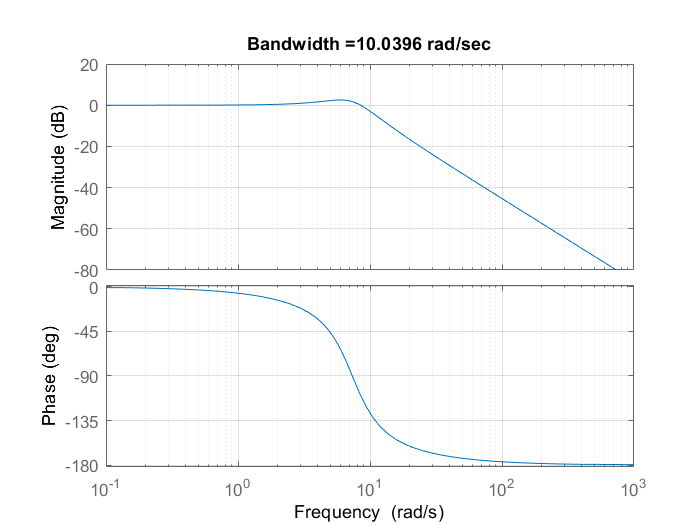

close all; clear;

fprintf("CP8.4 \n");

num = [54]; den = [1 6 0];
sys = tf(num, den);
sys_closed = feedback(sys,1);
wb = bandwidth(sys_closed);

title_name = strcat('Bandwidth = ', num2str(wb), ' rad/sec');
figure; bode(sys_closed); grid on;
title(title_name);

CP 8.9

Design a filter, G(s), with the following frequency response:

- For $\omega <1\;\mathrm{rad}/s$, the magnitude $20\;{\mathrm{log}}_{10} |G\left(j\omega \right)|<0\;\mathrm{dB}$.

- For $1<\omega <1000\;\textrm{rad}/s$, the magnitude $20\;\log_{10} \left|G\left(j\omega \right)\right|\ge 0\;\textrm{dB}$.

- For $\omega >1000\;\textrm{rad}/s$, the magnitude $20\;\log_{10} \left|G\left(j\omega \right)\right|<0\;\textrm{dB}$.

Try to maximize the peak magnitude as close to $\omega =40\;\textrm{rad}/s$ as possible.

Ans.

$G\left(s\right)=K\frac{\sum_i \left(s+z_i \right)\;}{\sum_j \left(s+p_j \right)}$, K < 0 for initial condition 1.

zeros: 1, 1000; poles: two poles between 1 ~ 1000


$$\Longrightarrow \mathrm{My}\;\mathrm{design}\;\mathrm{of}\;\mathrm{this}\;\mathrm{system}\;G\left(s\right)=0\ldotp 6\;\frac{\left(s+1\right)\left(s+1000\right)}{\left(s+20\right)\left(s+80\right)}$$


close all; clear;
fprintf("CP8.9 \n");

CP8.9 



K = 0.6;
a1 = [1 1]; a2 = [1 1000]; a = conv(a1, a2); a = K*a;
b1 = [1 20]; b2 = [1 80]; b = conv(b1, b2);

sys = tf(a, b);
w = logspace(0,3,10000);

[mag, phase] = bode(sys, w);
[mp, wp_index] = max(mag);
wp = w(wp_index);

fprintf("peak magnitude at wp = %f rad/s", wp);

peak magnitude at wp = 40.064551 rad/s

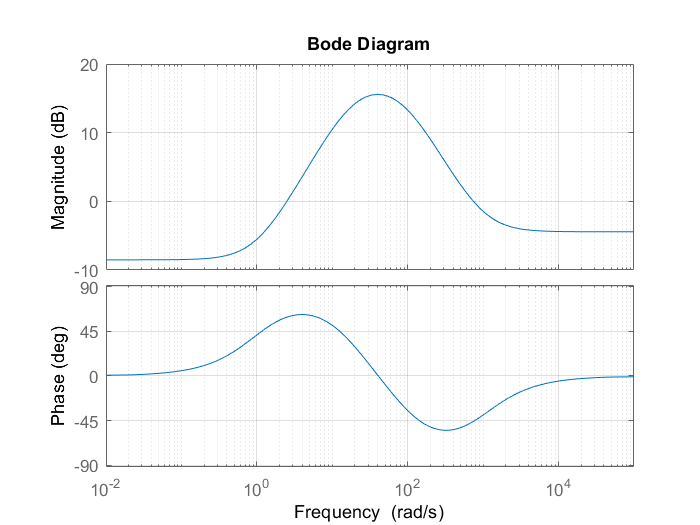

figure; bode(sys); grid on;

CP 9.3

Using the nichols function, obtain the Nichols chart with a grid for the following transfer functions:

(a) $G\left(s\right)=\frac{1}{s+0\ldotp 2}$

(b) $G\left(s\right)=\frac{1}{s^2 +2s+1}$

(c) $G\left(s\right)=\frac{6}{s^3 +6s^2 +11s+6}$

Determine the approximate phase and gain margins from the Nichols charts and label the charts accordingly.

close all; clear;
fprintf("CP9.3 \n");

CP9.3 


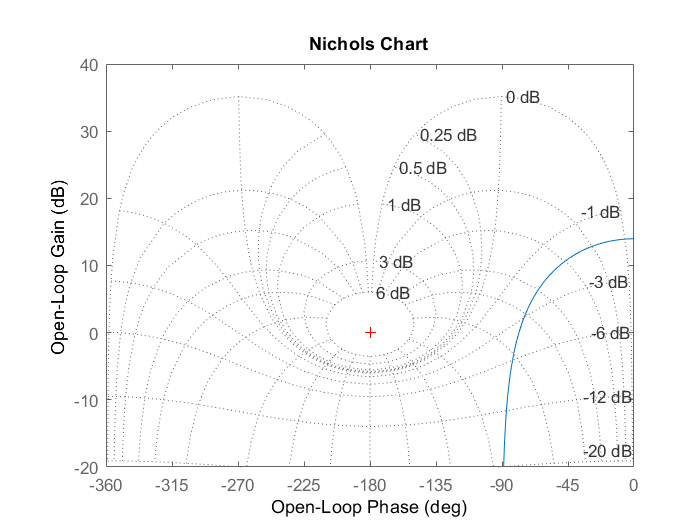


% a
a1 = [1]; b1 = [1 0.2];
sys1 = tf(a1, b1);
figure; nichols(sys1); ngrid;

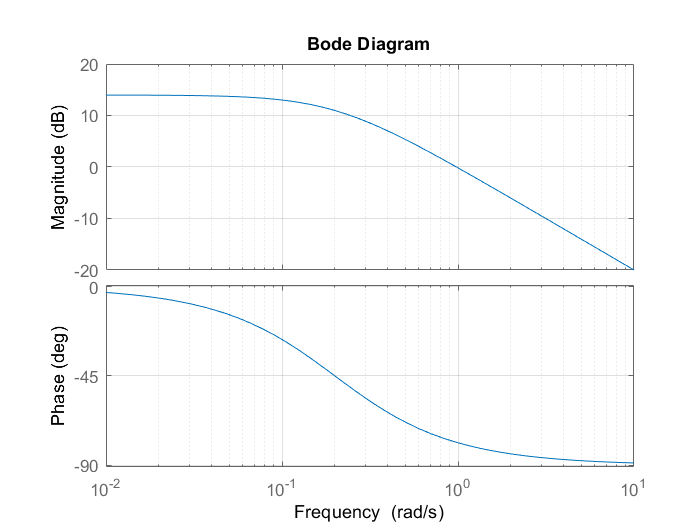

figure; bode(sys1); grid on;

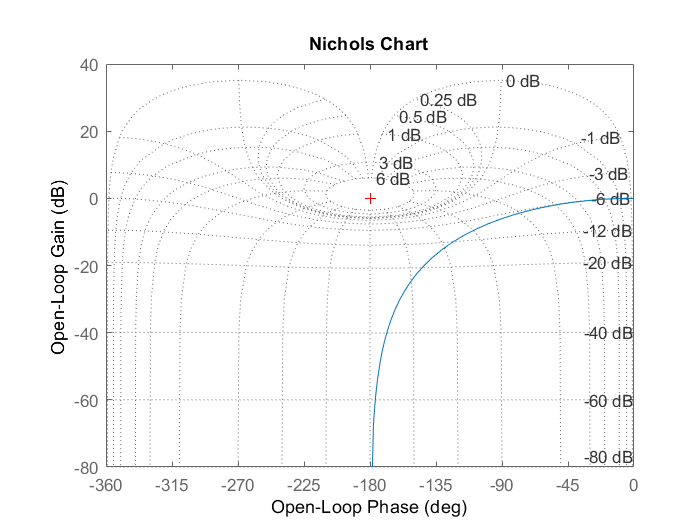


% b
a2 = [1]; b2 = [1 2 1];
sys2 = tf(a2, b2);
figure; nichols(sys2); ngrid;

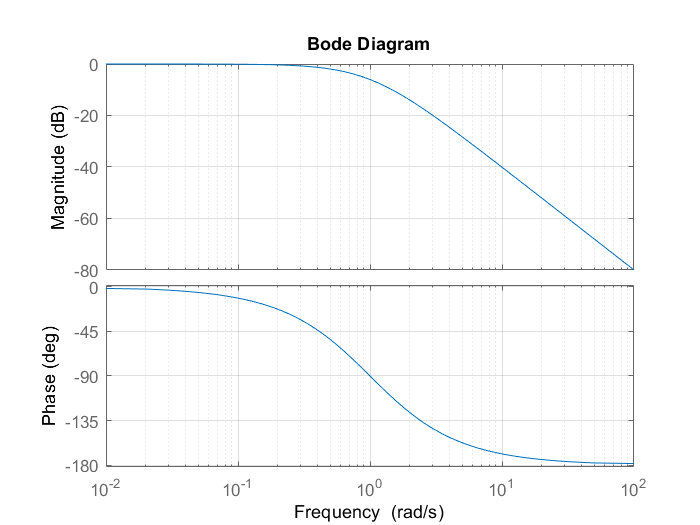

figure; bode(sys2); grid on;

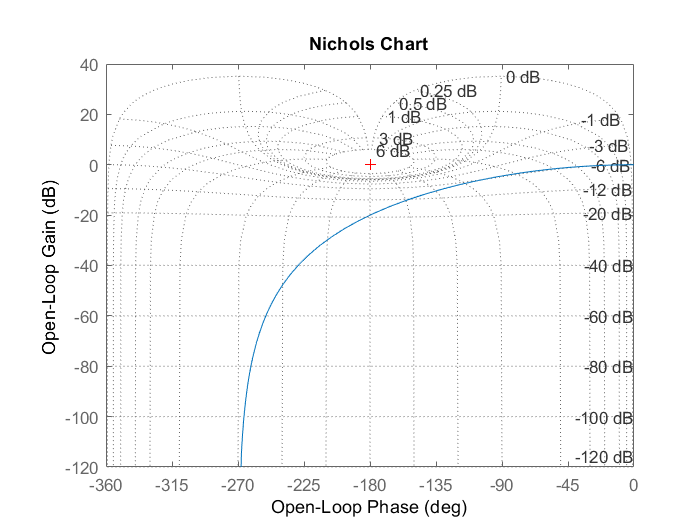


% c
a3 = [6]; b3 = [1 6 11 6];
sys3 = tf(a3, b3);
figure; nichols(sys3); ngrid;

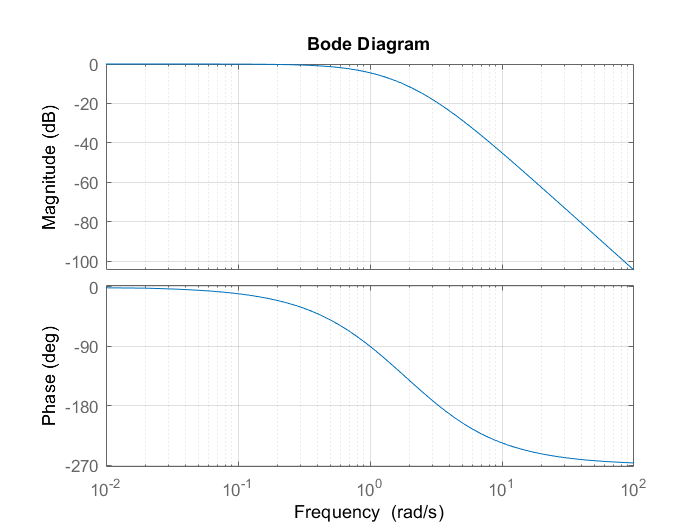

figure; bode(sys3); grid on;

(a) $G\ldotp M\ldotp =\infty \;\mathrm{and}\;P\ldotp M\ldotp ={120}^{\circ }$

(b) $G\ldotp M\ldotp =\infty \;\textrm{and}\;P\ldotp M\ldotp =\infty$

(c) $G\ldotp M\ldotp =20\mathrm{dB}\;\textrm{and}\;P\ldotp M\ldotp =\infty$